# Urbanisation: A Simulation Using Cellular Automata and Image Processing

## Context

Urbanisation is the phenomenon where people tend to group together around resources. These might be reliable water sources or food sources. However, resources are often finite, and there is overcrowding in the area. As a result, people spread out forming larger urban areas. This is known as urban sprawl.

## Simulating Urbanisation

Urbanization can be simulated using cellular automata. In this simulation, the standard rules of the Game of Life have been extended to include a new layer of resources. Beyond life and death, there is a new condition in which cells can be: resource-bound. Resource-bound is when the cells have found a resource. Instead of continuing the typical Game of Life, the cells become attached to resources and gradually deplete them. Neighboring rules apply to these groups, and as a result, a "city" is formed. However, as more people join the city, the resources deplete until the area no longer supports life. Then, cells return to their live state and continue the Game of Life until they come across a new resource. 

The area of these cities can be quantified through image processing. A gaussian blur can be applied to display the cities around resources as a 'heat map'. Also, the area of the cities can be calculated by counting the number of resource bound cells.

## Inputs

To run the simulation, we must call the function urban_sprawl, with the inputs 

- R (rows)

- C (columns)

- number_of_resources (the number of resource locations)

- num_steps (the number of steps in the simulation) 

- resource_value (the amount avaliable to be depleted from resource locations) 

- spawn_density (the density of people in the spawn location)

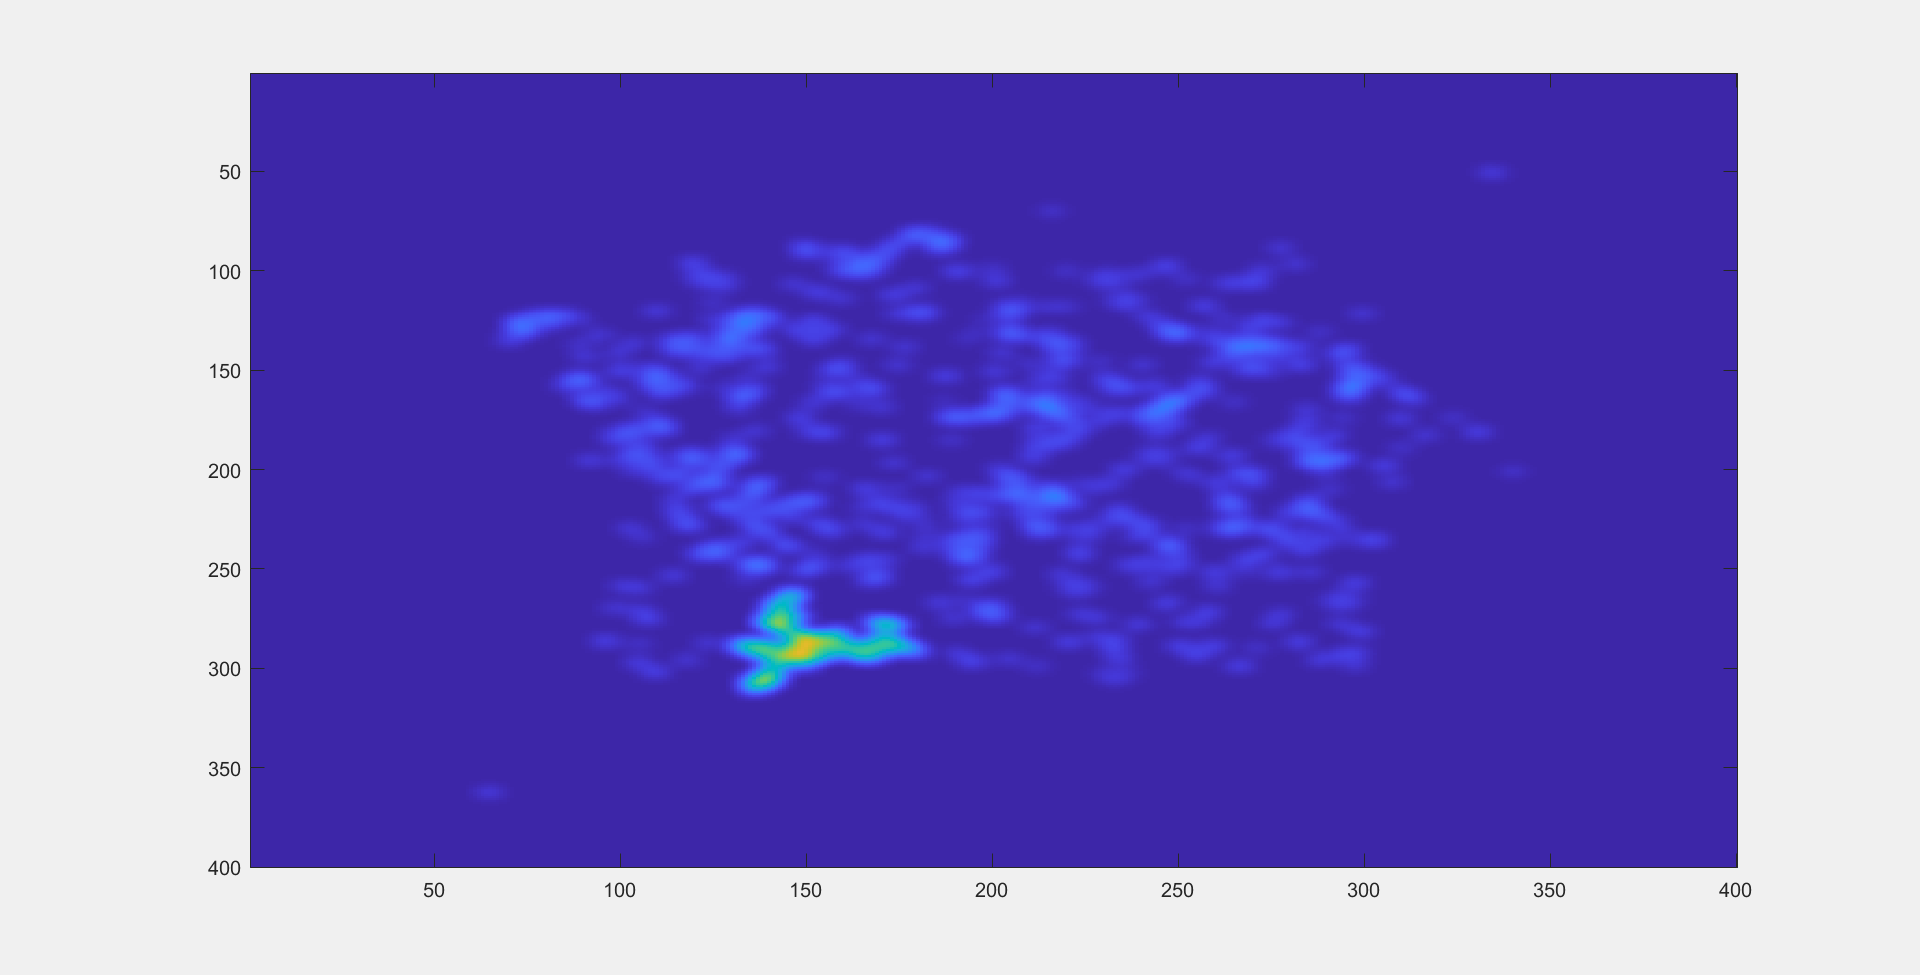

urban_sprawl(400,400,3,1000,100,0.2)

When you run the function, a visualisation of the simulation is played, and then the plot of the proportion of green pixels, a.k.a resource bound cells in a city is displayed, like the images below:

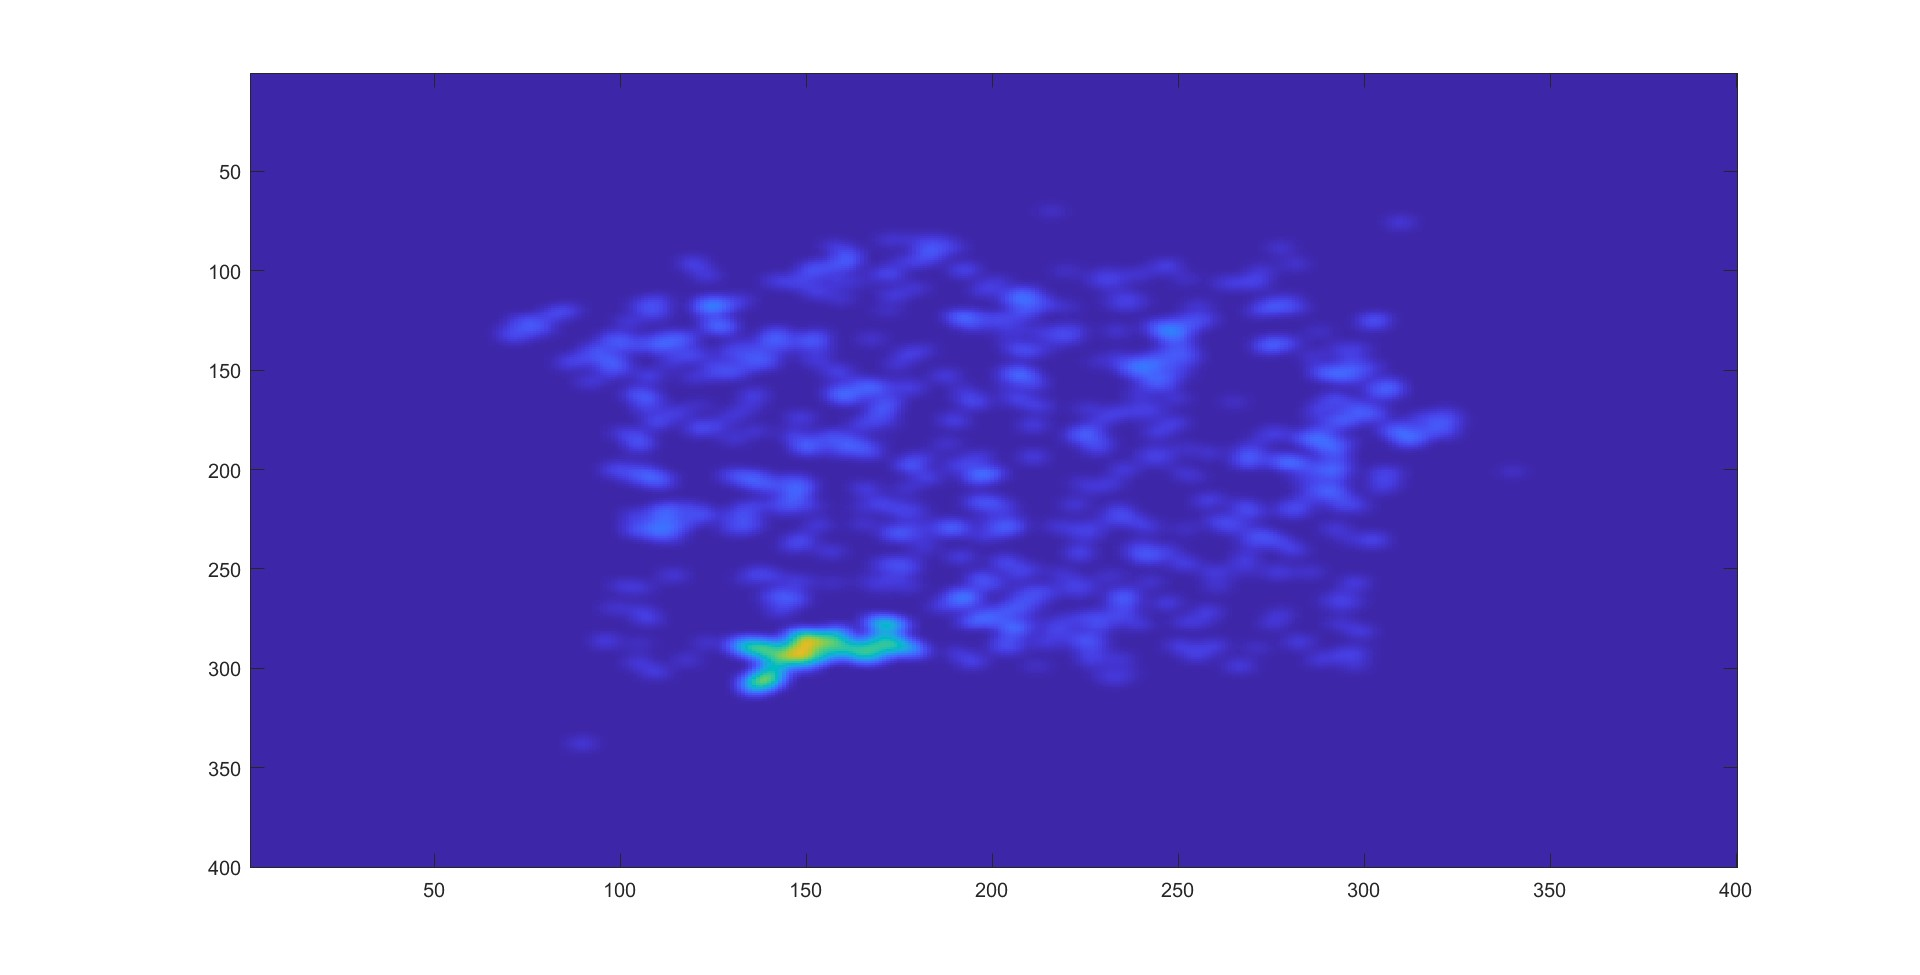

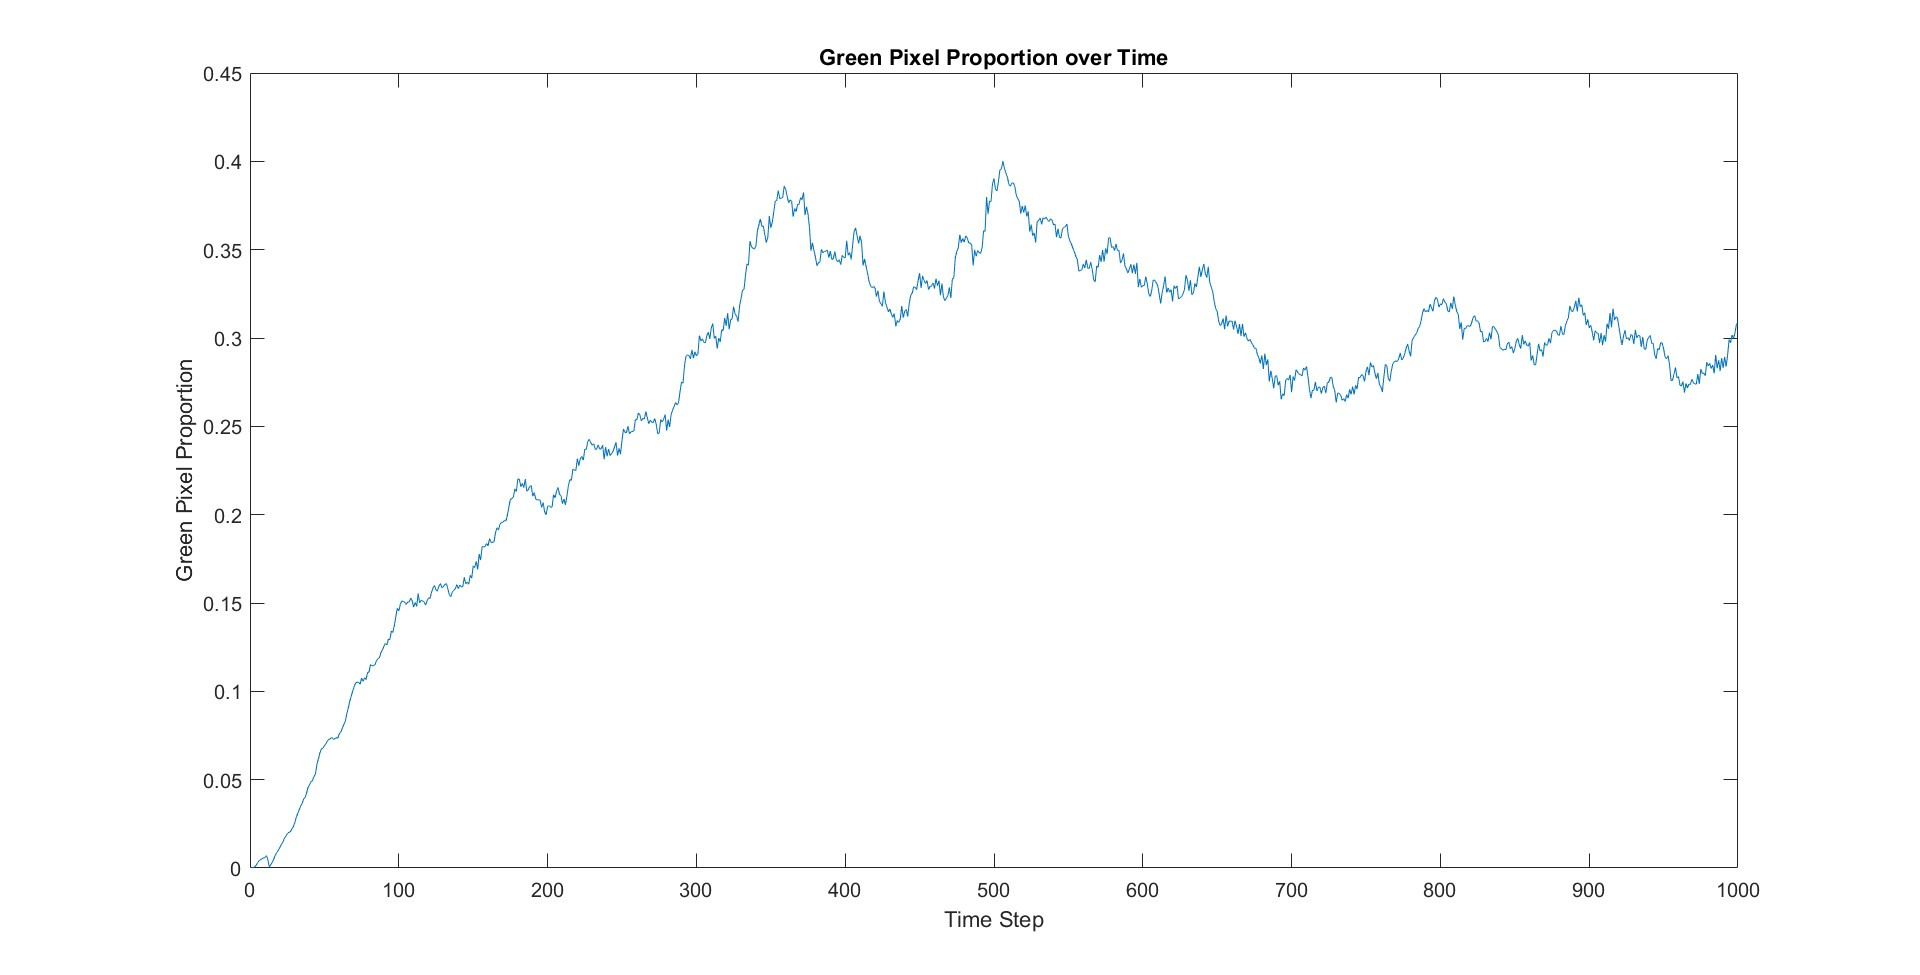

We can see as time goes on, more cells settle in the region of the resources. However, once the resource count gets lower, urban sprawl occurs as cells move away or die out in search of less crowded resources. 

## It's better to stick together

Sometimes, the simulation shows no development of cities - no one finds the resources. Therefore, we just see a simple game of life simulation. This results in fewer survivors than when a city is established, demonstrating the advantage of grouping together.

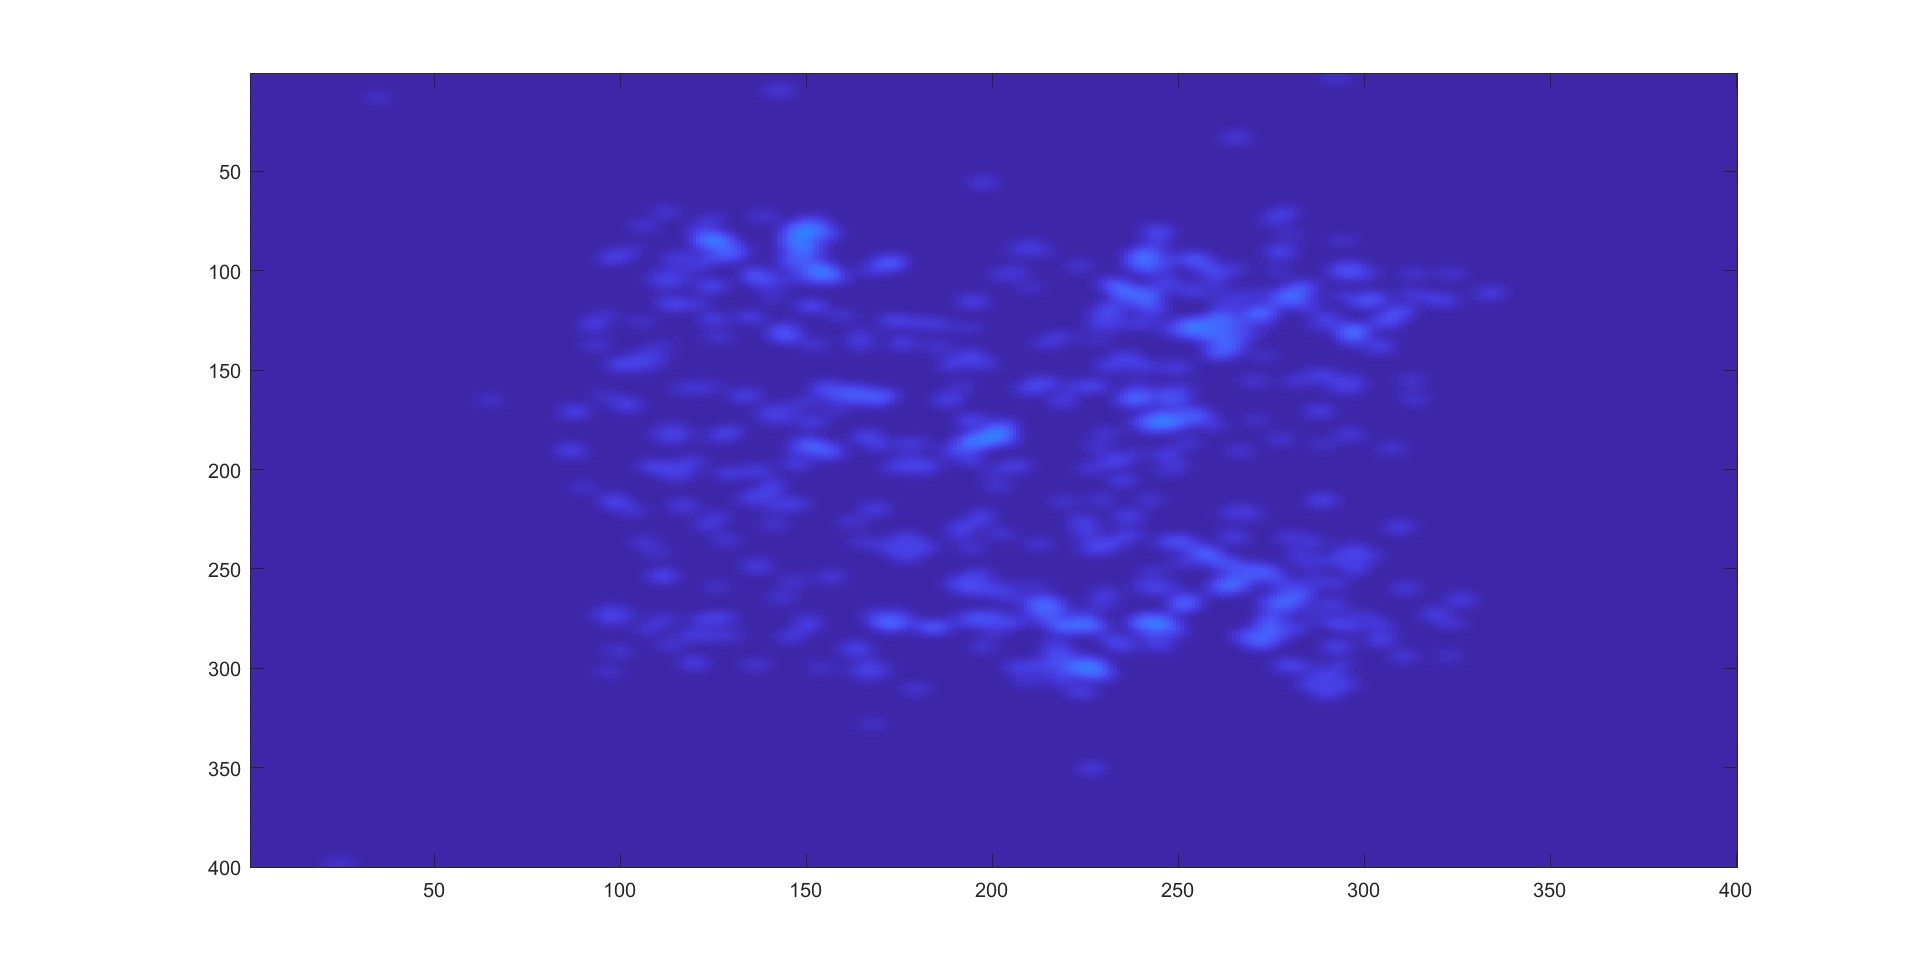

## Its always better down where its wetter

You can input more resource areas into the simulation, and try and find out how much you need to support a population of your initial population density (essentially number of people). You can also decrease the simulation area to see if that makes it easier for cells to find resources.

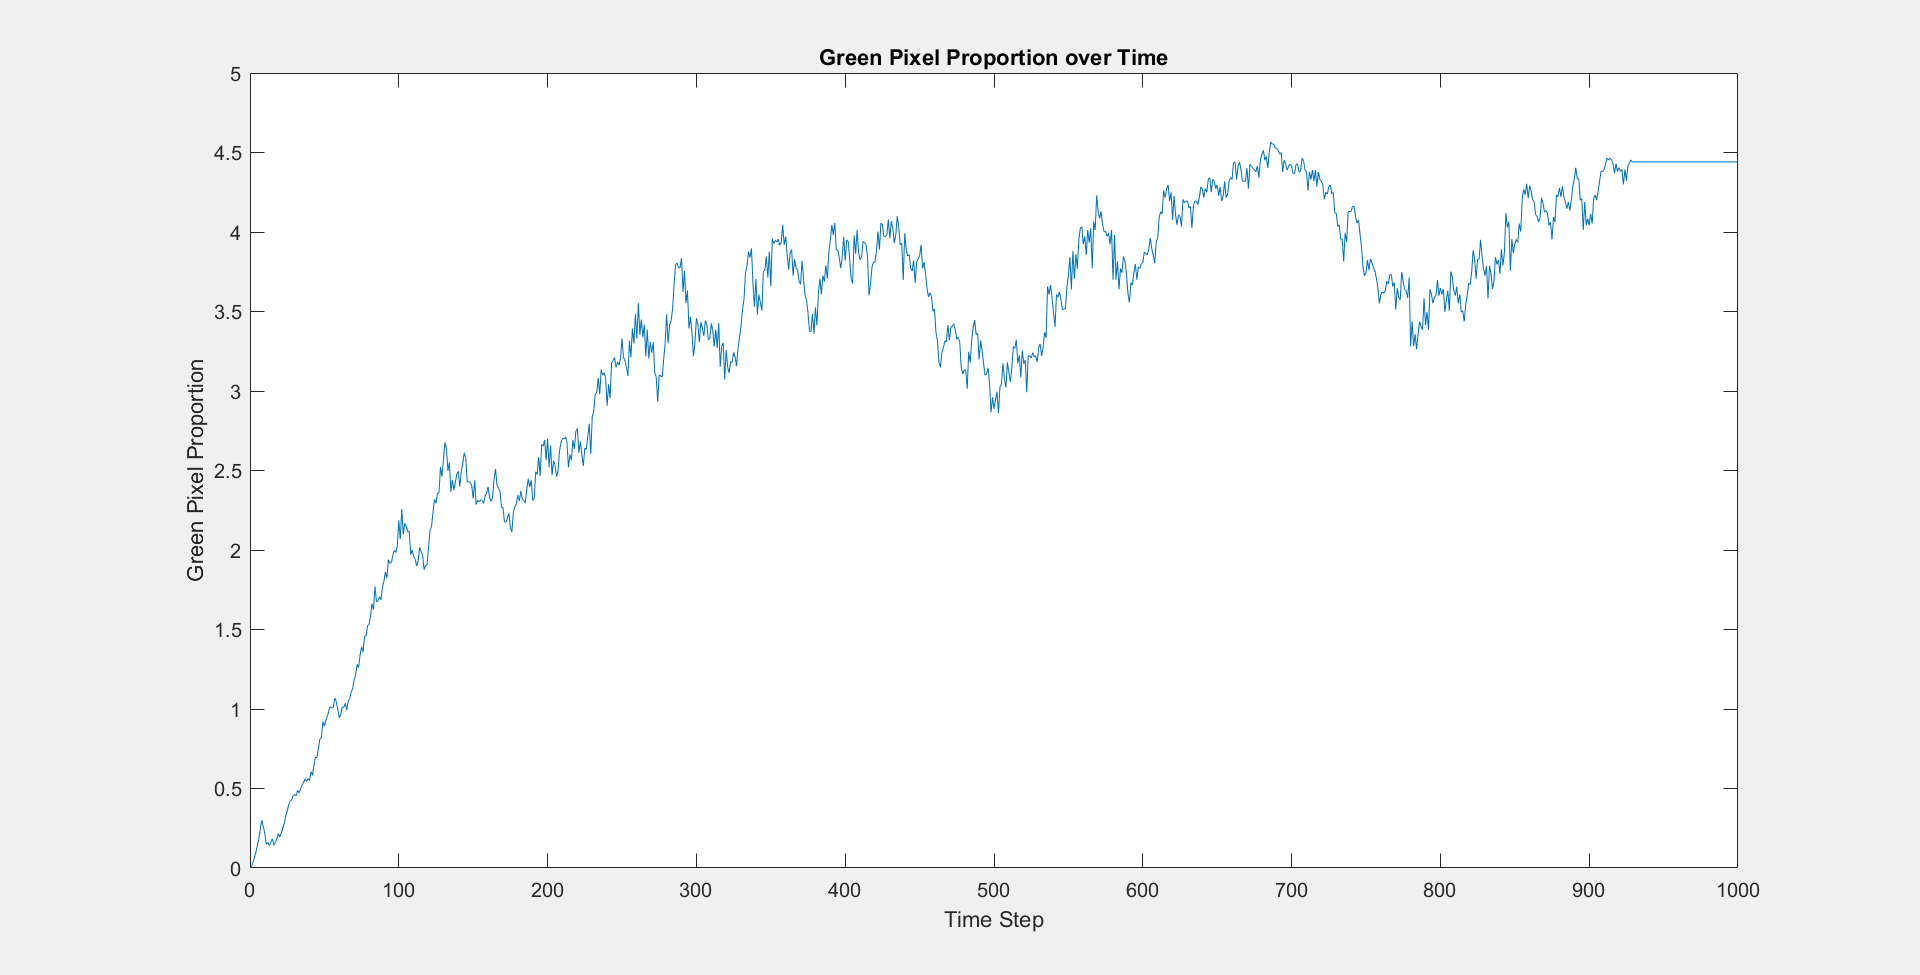

urban_sprawl(200,200,100,1000,100,0.2)

When there is an abundance of resources, the cities become large and complex. Much like real life, areas rich in resources are the most densley populated, such as coastal areas in Australia, compared to inland areas. 

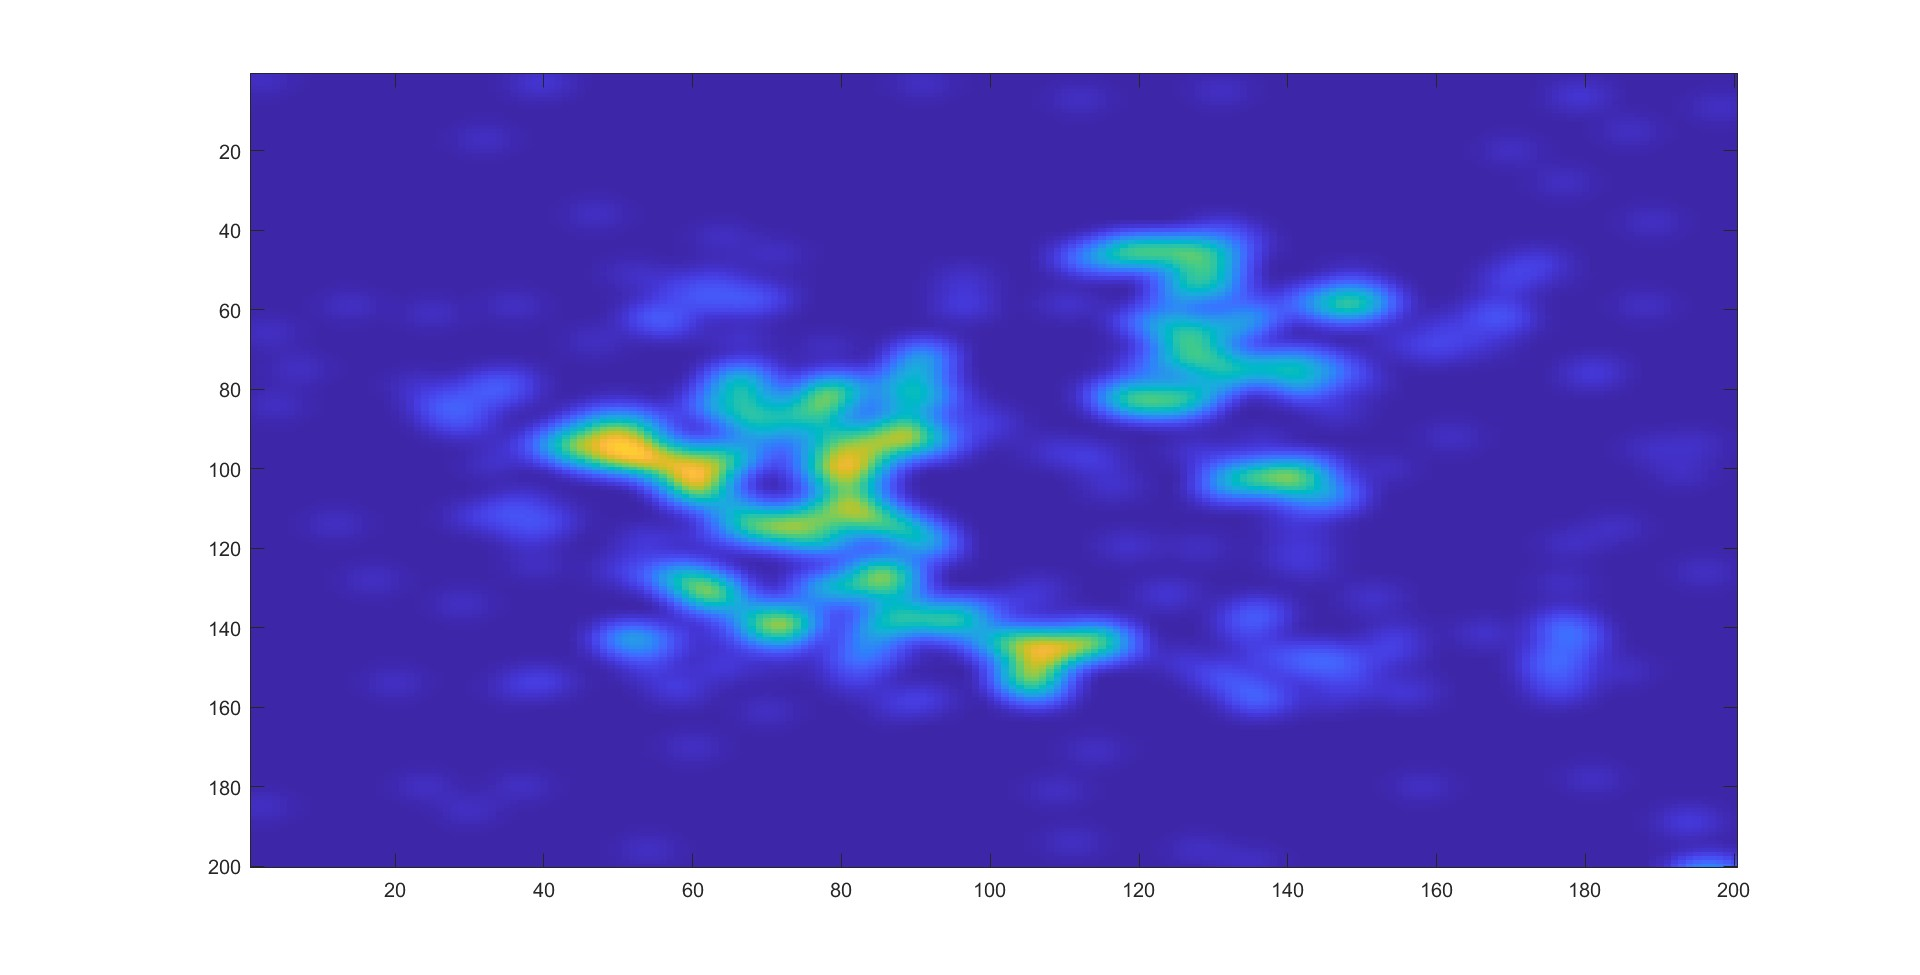

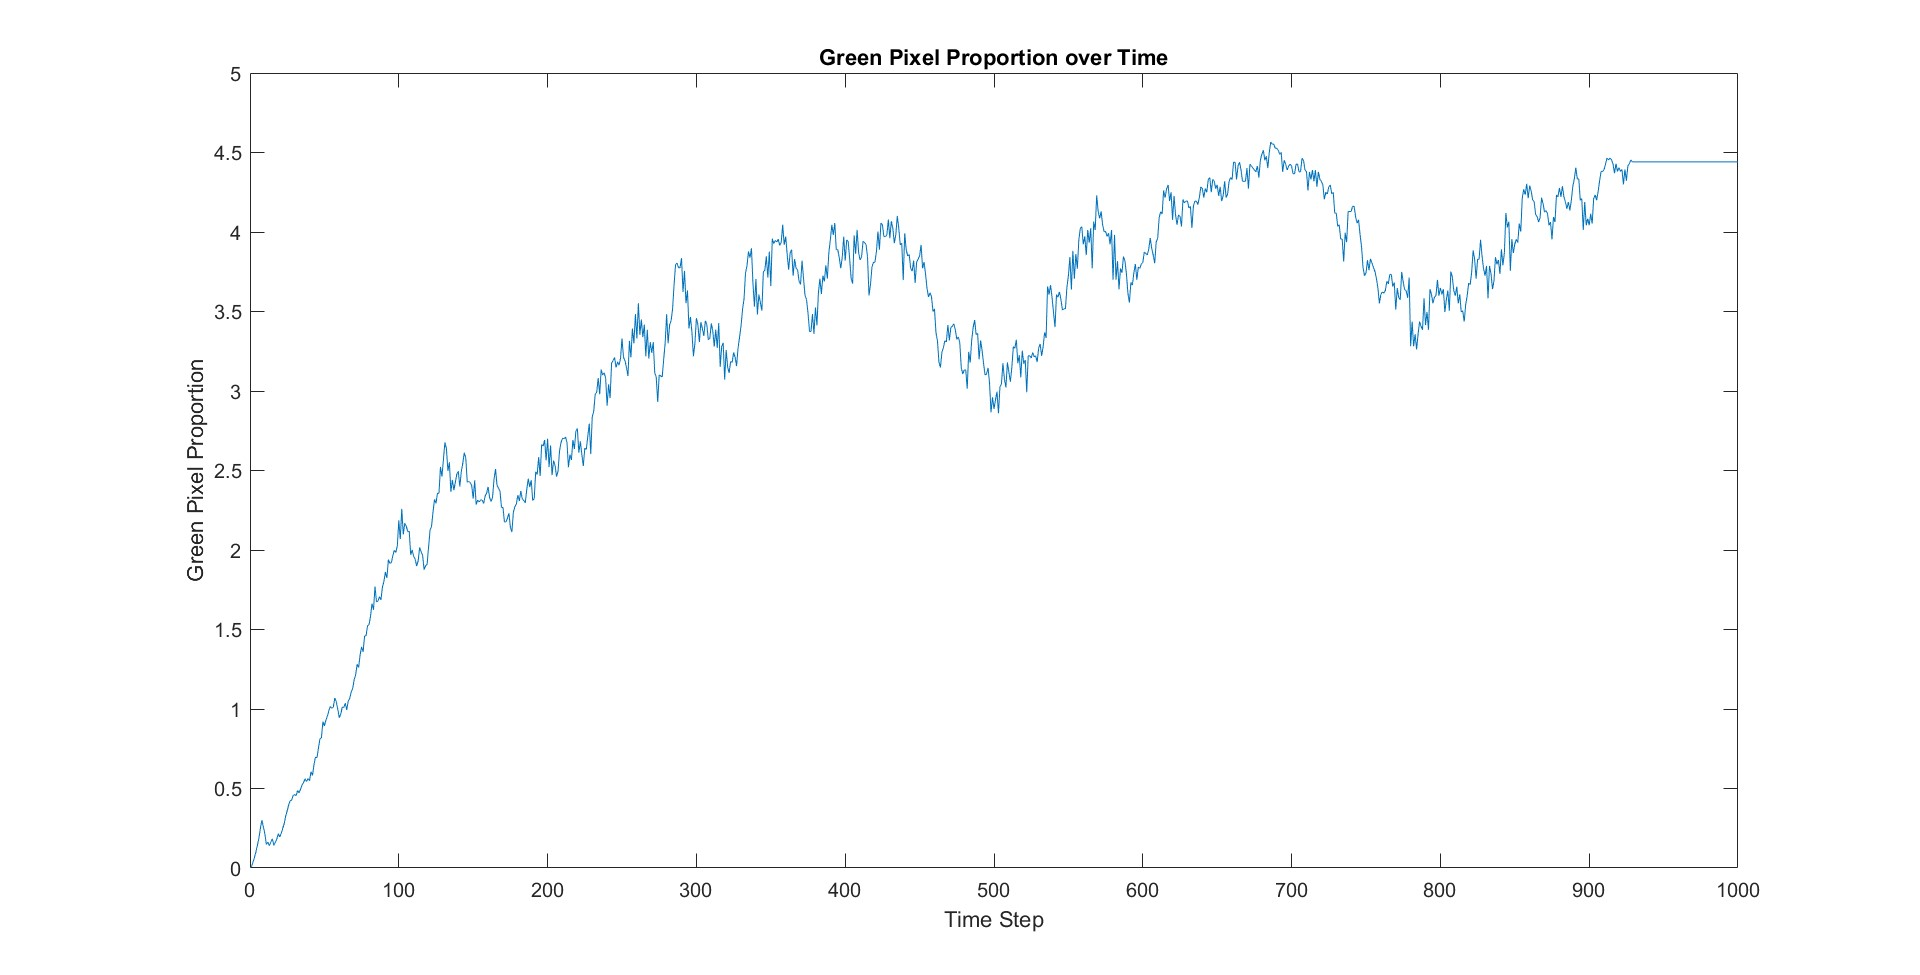

## How the code works

In the function urban_sprawl(0, there are several layers to displaying the simulation you've just seen.